# Assignment B

## Set up

clear all;
close all;
clc;
load('ECP_values.mat');
% Physical system parameters
J_1 = ECP_values(1);            % Disk 1 inertia kgm^2
J_2 = ECP_values(2);            % Disk 2 inertia kgm^2
J_3 = ECP_values(3);            % Disk 3 inertia kgm^2
k_1 = ECP_values(4);            % Shaft 1-2 stiffness Nm/rad
k_2 = ECP_values(5);            % Shaft 2-3 stiffness Nm/rad
b_1 = mean(ECP_values([6 7]));  % Disk 1 damping and friction Nms/rad
b_2 = mean(ECP_values([8 9]));  % Disk 2 damping and friction Nms/rad
b_3 = mean(ECP_values([10 11]));% Disk 3 damping and friction Nms/rad
T_Cp = ECP_values(12);          % Disk 1 Coulomb friction in positive direction
T_Cm = ECP_values(13);          % Disk 1 Coulomb friction in negative direction
atan_scale = 100;               % Sign approximation factor
w_th = 0.75;                    % Threshold angular velocity rad/s

% The system states are [theta_1;omega_1;theta_2;omega_2;theta_3;omega_3]
x_0 = [0;0;0;0;0;0];            % Initial conditions
T_s = 0.004;                    % Sampling period
sigma_meas = 0.0093*eye(3);     % Measurements covariance matrix



%% State space representation
syms f_theta1 f_theta2 f_theta3 f_u1 f_u2 theta1 omega1 theta2 omega2 theta3 omega3
syms u1 u2 y1 y2 y3 %b_1 b_2 b_3 J_1 k_1 k_2
x = [theta1 omega1 theta2 omega2 theta3 omega3].';
u = [u1 u2].';
y = [y1 y2 y3].';
f = [f_theta1 f_theta2 f_theta3 f_u1 f_u2].';
A = [0, 1, 0, 0, 0, 0;
     -k_1/J_1, -b_1/J_1, k_1/J_1, 0, 0, 0;
     0, 0, 0, 1, 0, 0;
     k_1/J_2, 0, -(k_1 + k_2)/J_2, -b_2/J_2, k_2/J_2, 0;
     0, 0, 0, 0, 0, 1;
     0, 0, k_2/J_3, 0, -k_2/J_3, -b_3/J_3];
B = [0 0
     1/J_1 0
     0 0
     0 1/J_1
     0 0
     0 0];
C = [1 0 0 0 0 0
     0 0 1 0 0 0
     0 0 0 0 1 0];
D = [0];
E_x = [0 -1/J_1 0 0 0 0].';
E_x2 = [0 0 0 0 0 0].';
E_y = zeros(3,1);
F_x = [zeros(6, 3), B];
F_y = [eye(3) zeros(3, 2)];

ThreeDiskSystem = ss(A,B,C,D);
disp(ThreeDiskSystem)

  3×2 ss array with properties:

                A: [6×6 double]
                B: [6×2 double]
                C: [3×6 double]
                D: [3×2 double]
                E: []
          Offsets: []
           Scaled: 0
        StateName: {6×1 cell}
        StatePath: {6×1 cell}
        StateUnit: {6×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [2×1 double]
      OutputDelay: [3×1 double]
        InputName: {2×1 cell}
        InputUnit: {2×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {3×1 cell}
       OutputUnit: {3×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



% ThreeDiskSystem.InputName = {'r';'fs'};


% %%%%%%%% SKIP THAT WHEN SIMULATING IN OPEN LOOP %%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Discrete time
% 
% %sys_d = [];
% %F_d = sys_d.A;
% %G_d = sys_d.B;
% 
% % State-feedback LQR design
% Q_c = diag([2 0 2 0 2.5 0.0024]);
% R_c = diag([10 10]);
% K_c = [];
% 
% % Scaling of reference
% C_ref = [];
% 
% % Kalman filter with friction estimation - DO NOT MODIFY
% F_aug = [F_d G_d(:,1);zeros(1,6) 1];
% G_aug = [G_d;0 0];
% C_aug = [C zeros(3,1)];
% % Kalman gain
% L_aug = dlqe(F_aug,eye(7),C_aug,1e-3*eye(7),sigma_meas(1,1).^2*eye(3));
% L_o = L_aug(1:6,:);
% L_d = L_aug(7,:);
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %% Residual filter design
% 
% %% Strong and weak detectability
% H_rf = tf(0);
% 
% %% GLR
% f_m = [0;-0.025;0];     % Sensor fault vector (added to [y1;y2;y3])
% theta = 0;                  % Put the threshold from GLR here
% 
% %% Virtual actuator
% % Failure in actuator 2
% % Do the desing first in continuous time
% va_eig_d = [];  % Discrete time eigenvalues
% va_eig = log(va_eig_d)/T_s;     % Continuous time eigenvalues
% % Then discretise your VA
% 
% B_change = [1 0;0 0];
% 
% %% Simulation for sensor fault (f_u = 0)
% simTime = 45;                   % Simulation duration in seconds
% f_u_time = 25;                  % Actuator fault occurence time
% detect_time = f_u_time + 3.75;
% f_u = [0;0];                    % Actuator fault vector (added to [u1;u2])
% u_fault = 0;                    % Disable VA meachanism
% f_m_time = 8.5;                 % Sensor fault occurence time
% sim('threeDiskOscillatorRig');
% 
% %% Simulation for actuator fault (f_m = 0)
% f_u = [0;-0.1];                 % Actuator fault vector (added to [u1;u2])
% u_fault = 1;                    % Enable VA meachanism
% f_m = [0;0;0];                  % Sensor fault vector (added to [y1;y2;y3])
% sim('threeDiskOscillatorRig');
% 
% %% Plot settings
% set(0,'DefaultTextInterpreter','latex');
% set(0,'DefaultAxesFontSize',20);
% set(0,'DefaultLineLineWidth', 2);

## Question 9

s = tf('s');
M = 3; A = 10^-4; omega_B = 4/1.5;

We = (s/M+omega_B)/(s+omega_B*A);   % W_1*S
Wu = (s*12+6)/(s+20);               % W_2*K*S
Wy = [];                            % W_3*T

ThreeDiskSystem.InputName = {'u1';'u2'};
ThreeDiskSystem.OutputName = {'y1';'y2';'y3'};

G = ThreeDiskSystem('y3', 'u1');

[K_inf,CL,gamma] = mixsyn(G, We^3, Wu, Wy);
fprintf('γ(gamma) = %.4f\n', gamma);

γ(gamma) = 1.3002


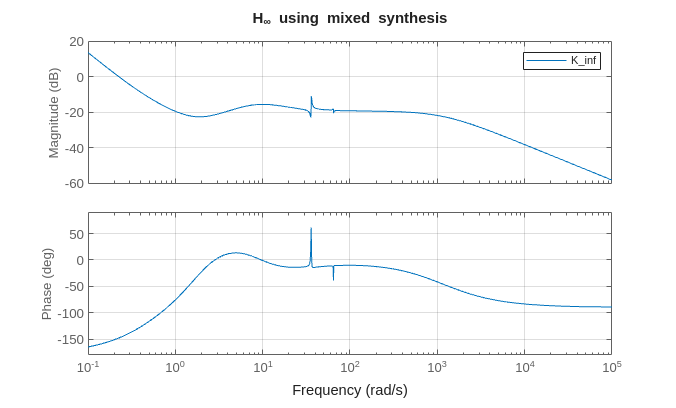

% Bode plot
figure(1)
bode(K_inf)
grid on
title('H_{\infty} using mixed synthesis')
legend()

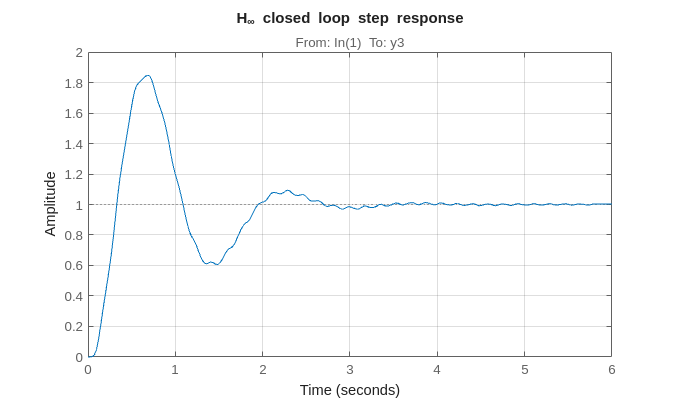


T_inf = feedback(G*K_inf, 1);
step(T_inf)
grid on
title('H_{\infty} closed loop step response')

## Question 10

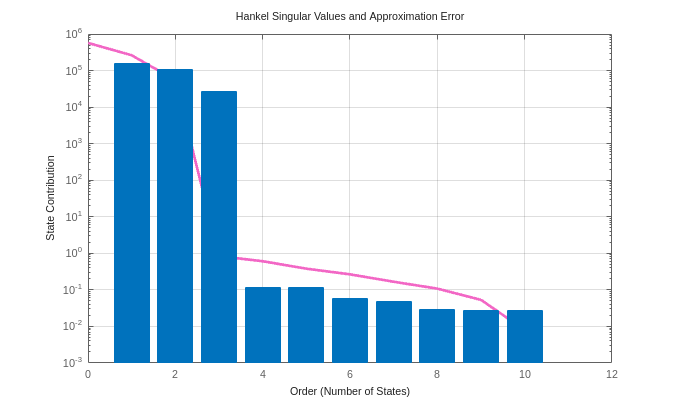

R = reducespec(K,"Balanced");
view(R)

rsys = getrom(R,Order=7);
isstable(rsys)

ans = logical
   1


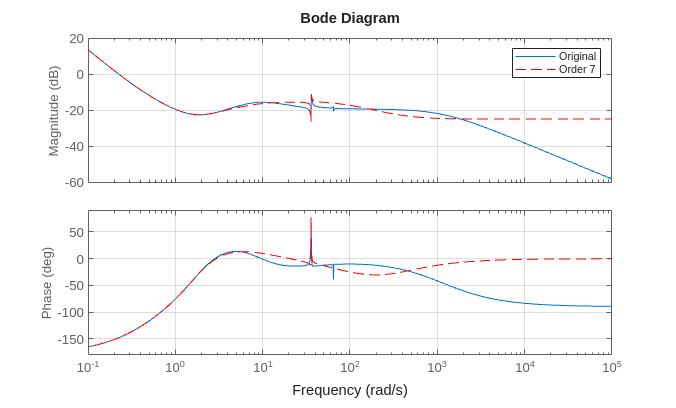

bode(K_inf,rsys,'r--')
grid on
legend("Original","Order 7")

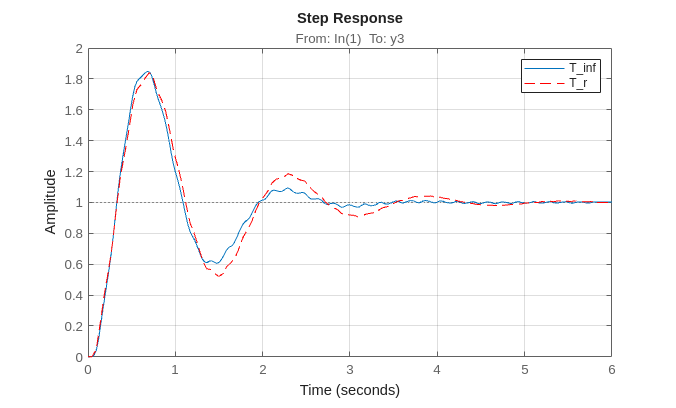

T_r = feedback(G*rsys,1);
step(T_inf,T_r,'r--')
grid on
legend()

## Question 11

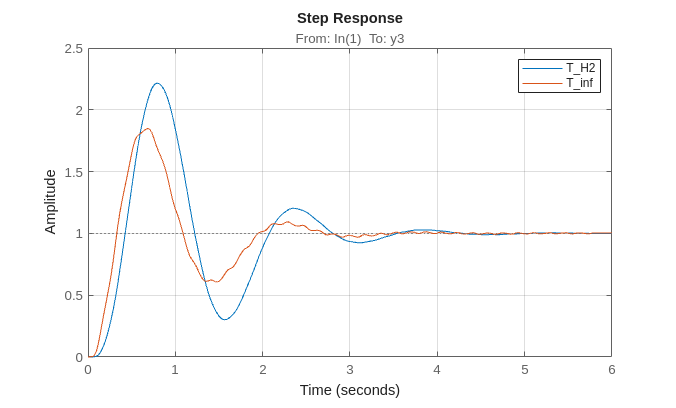

[K_H2, ~, ~] = mixsyn(G, We^3, Wu, Wy, 150);
% [KH2,CLH2,gammaH2] = h2syn(P, 1, 1);

T_H2 = feedback(G*K_H2, 1);
figure()
step(T_H2, T_inf)
grid on
legend()

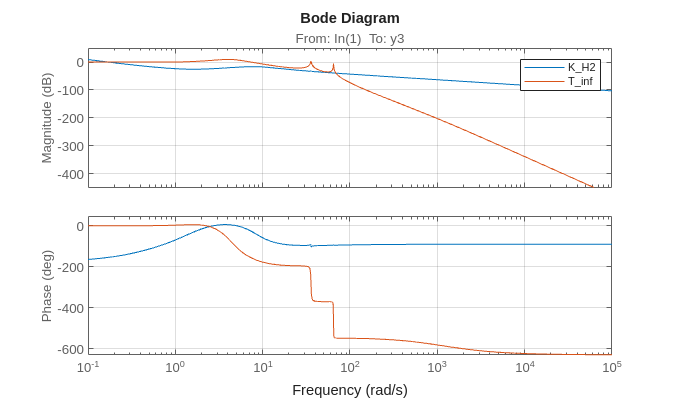

figure()
bode(K_H2, T_inf)
grid on
legend()